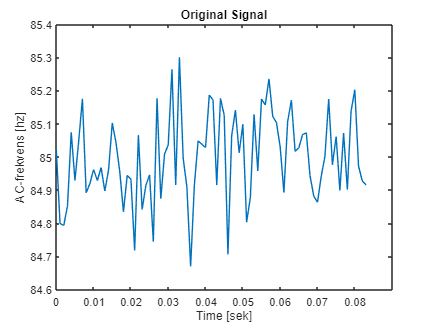

Matrix = csvread("C:\Users\fryde\Documents\Simon\magnitude_matrix.csv");
x = M(:, 10);   % All frequencies from the 10th column

fs = 1000;  % Sampling frequency
T = 1/fs;   % Sampling period

t = (0:T:length(x)*T-T)'; 


plot(t, Sig)
title("Original Signal")
xlabel('Time [sek]') 
ylabel('AC-frekvens [hz]')
xlim([0 0.09])
ylim([84.6 85.4])

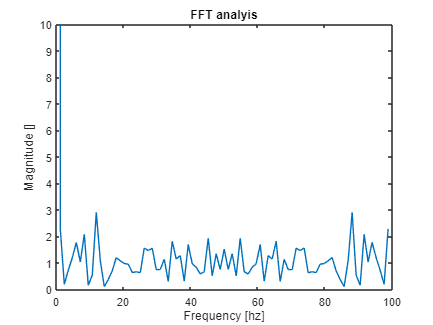

y = fft(x);    %Fast fourier transform                       
m = abs(y);    %Remove the imaginary componentens and determining the magnitude                        
y(m<1e-6) = 0; %remove tiny values
f = (0:length(y)-1)*100/length(y); %making a vector of frequencies


%%  Use the following plot to determine what frequencies you wish to
%%  eliminate.

plot(f, m)
title("FFT analyis")
xlabel('Frequency [hz]') 
ylabel('Magnitude []')
xlim([0 100])
ylim([0 10])

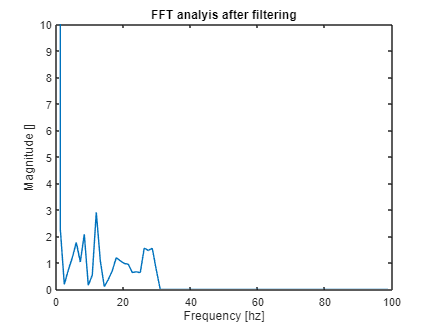

% Change the value of fc (cutoff frequency) to a desired value 
% from doing the frequency analysis.

fc = 30;
y(f>fc) = 0;
m = abs(y);

plot(f, m)
title("FFT analyis after filtering")
xlabel('Frequency [hz]') 
ylabel('Magnitude []')
xlim([0 100])
ylim([0 10])

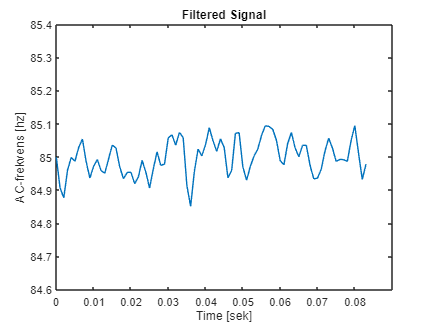

%Use inverse fft to get filtered signal
X = real(ifft(y));

plot(t, X)
title("Filtered Signal")
xlabel('Time [sek]') 
ylabel('AC-frekvens [hz]')
xlim([0 0.09])
ylim([84.6 85.4])